%Loading the user's file and create tables of data
HRData = input('Input your HR data with the filename and extension (e.g. flightdata.csv) and ensure it is on the MATLAB path: ','s')

HRData = 'Sample 1 Raven HR.csv'

HRFlightData = readtable(HRData, "VariableNamingRule","preserve")

HRFlightData = 38090×18 table
    Year    Month    Day        Time        Flight_Time_(s)    Sync    Gyro_X    Gyro_Y    Gyro_Z    Accel_X    Accel_Y    Accel_Z    Quat_1    Quat_2    Quat_3    Quat_4    Aux_Volts    Current
    ____    _____    ___    ____________    _______________    ____    ______    ______    ______    _______    _______    _______    ______    ______    ______    ______    _________


LRData = input('Input your LR data with the filename and extension (e.g. flightdata.csv) and ensure it is on the MATLAB path: ','s')

LRData = 'Sample 1 Raven LR.csv'

LRFlightData = readtable(LRData, "VariableNamingRule","preserve")

LRFlightData = 3800×101 table
    Year    Month    Day        Time        Flight_Time_(s)    Sync    Temperature_(F)    Baro_Press_(atm)    Baro_Altitude_ASL_(feet)    Baro_Altitude_AGL_(feet)    Batt_Volts    Apo_Volts    Main_Volts    3rd_Volts    4th_Volts    Velocity_Up    Velocity_DR    Velocity_CR    Inertial_Altitude    Inertial_DR_Position    Inertial_CR_position    Tilt_Angle_(deg)    Future_Angle_(deg)    Roll_Angle_(deg)    Reserved_1    Reserved_2    Reserved_3    Rocket_FER_Hex    Apo_FER_H  ex


%Join Tables
TtHRFlightData = table2timetable(HRFlightData, "RowTimes",'Time')

TtHRFlightData = 38090×17 timetable
        Time        Year    Month    Day    Flight_Time_(s)    Sync    Gyro_X    Gyro_Y    Gyro_Z    Accel_X    Accel_Y    Accel_Z    Quat_1    Quat_2    Quat_3    Quat_4    Aux_Volts    Current
    ____________    ____    _____    ___    _______________    ____    ______    ______    ______    _______    _______    _______    ______    ______    ______    ______    _________

TtLRFlightData = table2timetable(LRFlightData, "RowTimes",'Time')

TtLRFlightData = 3800×100 timetable
        Time        Year    Month    Day    Flight_Time_(s)    Sync    Temperature_(F)    Baro_Press_(atm)    Baro_Altitude_ASL_(feet)    Baro_Altitude_AGL_(feet)    Batt_Volts    Apo_Volts    Main_Volts    3rd_Volts    4th_Volts    Velocity_Up    Velocity_DR    Velocity_CR    Inertial_Altitude    Inertial_DR_Position    Inertial_CR_position    Tilt_Angle_(deg)    Future_Angle_(deg)    Roll_Angle_(deg)    Reserved_1    Reserved_2    Reserved_3    Rocket_FER_Hex    Apo_FER_H  

TtFlightData = synchronize(TtHRFlightData, TtLRFlightData, 'union')

TtFlightData = 38090×117 timetable
        Time        Year_TtHRFlightData    Month_TtHRFlightData    Day_TtHRFlightData    Flight_Time_(s)_TtHRFlightData    Sync_TtHRFlightData    Gyro_X    Gyro_Y    Gyro_Z    Accel_X    Accel_Y    Accel_Z    Quat_1    Quat_2    Quat_3    Quat_4    Aux_Volts    Current    Year_TtLRFlightData    Month_TtLRFlightData    Day_TtLRFlightData    Flight_Time_(s)_TtLRFlightData    Sync_TtLRFlightData    Temperature_(F)    Baro_Press_(atm)    Baro_Altitude_ASL_(feet)    Baro_Altitude_AGL_(feet)    Batt


%Remove NaN
CorrectedTtFlightData = rmmissing(TtFlightData)

CorrectedTtFlightData = 322×117 timetable
        Time        Year_TtHRFlightData    Month_TtHRFlightData    Day_TtHRFlightData    Flight_Time_(s)_TtHRFlightData    Sync_TtHRFlightData    Gyro_X    Gyro_Y    Gyro_Z    Accel_X    Accel_Y    Accel_Z    Quat_1    Quat_2    Quat_3    Quat_4    Aux_Volts    Current    Year_TtLRFlightData    Month_TtLRFlightData    Day_TtLRFlightData    Flight_Time_(s)_TtLRFlightData    Sync_TtLRFlightData    Temperature_(F)    Baro_Press_(atm)    Baro_Altitude_ASL_(feet)    Baro_Altitude_AGL_(feet)    

FilledTtFlightData = fillmissing(TtFlightData, "nearest")

FilledTtFlightData = 38090×117 timetable
        Time        Year_TtHRFlightData    Month_TtHRFlightData    Day_TtHRFlightData    Flight_Time_(s)_TtHRFlightData    Sync_TtHRFlightData    Gyro_X    Gyro_Y    Gyro_Z    Accel_X    Accel_Y    Accel_Z    Quat_1    Quat_2    Quat_3    Quat_4    Aux_Volts    Current    Year_TtLRFlightData    Month_TtLRFlightData    Day_TtLRFlightData    Flight_Time_(s)_TtLRFlightData    Sync_TtLRFlightData    Temperature_(F)    Baro_Press_(atm)    Baro_Altitude_ASL_(feet)    Baro_Altitude_AGL_(feet)    

%Plotting x-axis Options through a menu and function
xMsg = "Choose the Variable for the x-axis"

xMsg = "Choose the Variable for the x-axis"


xMenuOptions = ["Time", ...
    "Gyro and Acceleration", ...
    "Enviroment", ...
    "Altitude", ...
    "Device Information", ...
    "Velocity", ...
    "Angle and Roll"]

xMenuOptions = 1×7 string array
    "Time"    "Gyro and Acceleration"    "Enviroment"    "Altitude"    "Device Information"    "Velocity"    "Angle and Roll"



xChoice = menu(xMsg,xMenuOptions)

xChoice = 1


xTimeOption = ["Time"]

xTimeOption = "Time"

xGyroAndAccelerationOption = ["Gyro_X", "Gyro_Y", "Gyro_Z", "Accel_X", "Accel_Y", "Accel_Z"]

xGyroAndAccelerationOption = 1×6 string array
    "Gyro_X"    "Gyro_Y"    "Gyro_Z"    "Accel_X"    "Accel_Y"    "Accel_Z"


xEnviromentOption = ["Temperature_(F)", "Baro_Press_(atm)"]

xEnviromentOption = 1×2 string array
    "Temperature_(F)"    "Baro_Press_(atm)"


xAltitudeOption = ["Baro_Altitude_ASL_(feet)", "Baro_Altitude_AGL_(feet)","Inertial_Altitude"]

xAltitudeOption = 1×3 string array
    "Baro_Altitude_ASL_(feet)"    "Baro_Altitude_AGL_(feet)"    "Inertial_Altitude"


xDeviceInformation = ["Batt_Volts"]

xDeviceInformation = "Batt_Volts"

xVelocityOptions = ["Velocity_Up", "Velocity_DR", "Velocity_CR"]

xVelocityOptions = 1×3 string array
    "Velocity_Up"    "Velocity_DR"    "Velocity_CR"


xAngleAndRollOptions = ["Tilt_Angle_(deg)", "Future_Angle_(deg)"]

xAngleAndRollOptions = 1×2 string array
    "Tilt_Angle_(deg)"    "Future_Angle_(deg)"



switch xChoice
    case 1
        xVars = menu(xMsg,xTimeOption)
    case 2
        xVars = menu(xMsg,xGyroAndAccelerationOption)
    case 3
        xVars = menu(xMsg,xEnviromentOption)
    case 4
        xVars = menu(xMsg,xAltitudeOption)
    case 5
        xVars = menu(xMsg,xDeviceInformation)
    case 6
        xVars = menu(xMsg,xVelocityOptions)
    case 7
        xVars = menu(xMsg,xAngleAndRollOptions)
end

xVars = 1

%Plotting y-axis Options through a menu and function
yMsg = "Choose the Variable for the y-axis"

yMsg = "Choose the Variable for the y-axis"


yMenuOptions = ["Time", ...
    "Gyro and Acceleration", ...
    "Enviroment", ...
    "Altitude", ...
    "Device Information", ...
    "Velocity", ...
    "Angle and Roll"]

yMenuOptions = 1×7 string array
    "Time"    "Gyro and Acceleration"    "Enviroment"    "Altitude"    "Device Information"    "Velocity"    "Angle and Roll"



yChoice = menu(yMsg,yMenuOptions)

yChoice = 4


yTimeOption = ["Time"]
yGyroAndAccelerationOption = ["Gyro_X", "Gyro_Y", "Gyro_Z", "Accel_X", "Accel_Y", "Accel_Z"]
yEnviromentOption = ["Temperature_(F)", "Baro_Press_(atm)"]
yAltitudeOption = ["Baro_Altitude_ASL_(feet)", "Baro_Altitude_AGL_(feet)","Inertial_Altitude"]
yDeviceInformation = ["Batt_Volts"]
yVelocityOptions = ["Velocity_Up", "Velocity_DR", "Velocity_CR"]
yAngleAndRollOptions = ["Tilt_Angle_(deg)", "Future_Angle_(deg)"]

switch yChoice
    case 1
        yVars = menu(yMsg,yTimeOption)
    case 2
        yVars = menu(yMsg,yGyroAndAccelerationOption)
    case 3
        yVars = menu(yMsg,yEnviromentOption)
    case 4
        yVars = menu(yMsg,yAltitudeOption)
    case 5
        yVars = menu(yMsg,yDeviceInformation)
    case 6
        yVars = menu(yMsg,yVelocityOptions)
    case 7
        yVars = menu(yMsg,yAngleAndRollOptions)
end

yVars = 1

yTimeOption = "Time"

yGyroAndAccelerationOption = 1×6 string array
    "Gyro_X"    "Gyro_Y"    "Gyro_Z"    "Accel_X"    "Accel_Y"    "Accel_Z"


yEnviromentOption = 1×2 string array
    "Temperature_(F)"    "Baro_Press_(atm)"


yAltitudeOption = 1×3 string array
    "Baro_Altitude_ASL_(feet)"    "Baro_Altitude_AGL_(feet)"    "Inertial_Altitude"


yDeviceInformation = "Batt_Volts"

yVelocityOptions = 1×3 string array
    "Velocity_Up"    "Velocity_DR"    "Velocity_CR"


yAngleAndRollOptions = 1×2 string array
    "Tilt_Angle_(deg)"    "Future_Angle_(deg)"


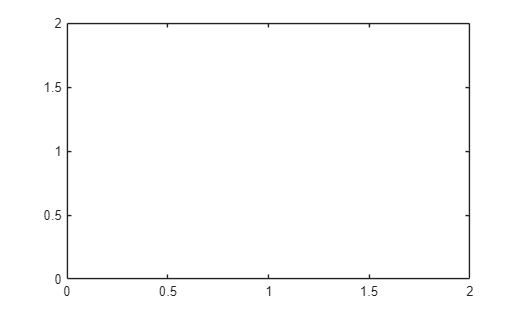

%Plotting
plot(xVars,yVars)